# **ASL American Sign Language Detection using Bayesian Networks and Convolutional Neural Networks**

## Course “Advanced Data Analysis and Machine Learning”

### **Project work 2**

### Authors: 

#### Thanh Tran (000285359)

#### Nghia Nguyen (000275466)

#### Swapnil Baad (000323486)

Report can be accessed with read-only priviledge from [Group_ASL_A2_report.docx](https://lut-my.sharepoint.com/:w:/g/personal/thanh_tran_student_lut_fi/ERNxVSaZ6XhNpJh_Ecmp26oBOtcaGtWC5TtH-ybKX2-_Uw?e=hczf4M)

## SETUP

clear all, clc, close all;

% Change the current folder to the folder of this m-file.
if(~isdeployed)
  cd(fileparts(matlab.desktop.editor.getActiveFilename));
end
% Add path to BNT toolbox
authors = ["ThanhTran", "NghiaNguyen", "SwapnilBaad"];

path_to_BNT = "C:\Users\thanh\bnt";
addpath(genpath(path_to_BNT));

folderPath = 'C:\Users\swapn\Downloads\bnt-master\bnt-master';
addpath(genpath(folderPath));

% Add services folder containing helper functions
addpath('./services');
% Add extracted data folder
addpath('./extracted_features');

% -------------- FEEL FREE TO DEFINE THE BOOLEAN VALUES HERE TO INCLUDE OR
% EXCLUDE RUNNING STEPS IN THE NEXT RUN ---------------------------------%

% BAYESIAN NETWORK & NAIVE BAYESIAN
Training_data_loading               = false;
Testing_data_loading                = false;
Feature_extraction_1_example        = false;
Feature_extraction_1_actual         = false;    % This step takes 5hours
Feature_extraction_2_example        = false;
Feature_extraction_2_actual         = false;    % This step takes even more. Therefore, extracted data has been saved for later use.
Data_transformation                 = false;
Bayesian_training                   = true;
Bayesian_testing                    = true;
NaiveBayesian_training              = false;

% CONVOLUTIONAL NEURAL NETWORK
CNN_transfer_learning_retraining_without_noise    = false;
CNN_transfer_learning_retraining_with_noise    = false;
SAVE_NEWLY_TRAINED_CNN_MODEL        = false;
CNN_transfer_learning_testing       = true;


## IMPORT DATA

### 1 Loading Training data

if Training_data_loading
    % Define environment variables
    class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"];                                    % All classes included in this project
    class_list = sort(class_list);
    nClass = length(class_list);                                 % The number of classes included
    
    
    train_data_path = "./data/asl_alphabet_train/asl_alphabet_train";                                  % File path to the directory of train data
    
    % Load images and convert to RGB data matrices
    Xtemplates_filename = {};
    Ytemplates = [];
    Xtrain = {};
    Ytrain = [];
    nTrainSamplePerClass = zeros(nClass, 1);
    disp("Training data loading ...");

    for c = 1:nClass    
        class_dir = sprintf(train_data_path + "/" + class_list(c));
        file_list = dir(class_dir);
        file_list = file_list(3:end);
        nImage = length(file_list);
        nTrainSamplePerClass(c) = nImage;
        for i = 1:nImage
            path_to_image = sprintf(class_dir + "/" + file_list(i).name);
            image_RGB = imread(path_to_image);
            image_gray = rgb2gray(image_RGB);
            Xtrain{end+1} = image_gray;
            Ytrain = [Ytrain; class_list(c)];
            
            % Get one every 100 images per class and save as templates of class
%             if ismember(i, 1:100:nImage)
%                 Xtemplates_filename{end+1} = path_to_image;
%                 Ytemplates = [Ytemplates, class_list(c)];
%             end
    
        end
    
        fprintf('   Class %s loading done.\n', class_list(c));
    end

%     save extracted_features\templates.mat Xtemplates_filename Ytemplates
    
%     save extracted_features\Ytrain.mat Ytrain

    nXtrain = length(Xtrain);
    Cum_nTrainSamplePerClass = cumsum(nTrainSamplePerClass);
end

### 2 Loading testing data

if Testing_data_loading
    test_data_path = "./data/asl_alphabet_test/asl_alphabet_test";                                     % File path to the directory of test data
    Xtest = {};
    Ytest = [];
    nTestSamplePerClass = zeros(nClass, 1);
    disp('Testing data loading ...');
    
    file_list = dir(test_data_path);
    file_list = file_list(3:end);
    regex_class = sprintf('%s-%s', class_list(1), class_list(end));
    regex_file_name = sprintf('^(?<file_name>[%s]_test.jpg)', regex_class);
    test_files_cell = regexpi({file_list.name}, regex_file_name, 'names','lineanchors');
    test_files = vertcat(test_files_cell{:})
    nXtest = length(test_files);
    
    for f = 1:nXtest
        file_name = test_files(f).file_name;
        
        path_to_image = sprintf(test_data_path + "/" + file_name);
        image_RGB = imread(path_to_image);
        image_gray = rgb2gray(image_RGB);
        Xtest{end+1} = image_gray;
        Ytest = [Ytest; file_name(1)];
    end
end

## FEATURE EXTRACTION

### 1 Hand segmentation and SIFT Feature Extraction

#### 1.1 Examples with visualization

if Feature_extraction_1_example && Training_data_loading
    nExample = 1;
    nExampleClass = 3;
    for c = 1:nExampleClass
        fprintf('Class %s feature extracting example(s):\n', class_list(c));
        sample_idxs = find(Ytrain == class_list(c), nExample);
        for i = 1:nExample
            SIFT_points = bound_key_region(Xtrain{sample_idxs(i)}, true);
        end
    end
end

#### 1.2 Actual Extraction

Xtrain_SIFTPoints_var_name = {'SP1x','SP1y','SP2x','SP2y','SP3x','SP3y','SP4x','SP4y','SP5x','SP5y'};

if Feature_extraction_1_actual && Training_data_loading
    nSIFTPoints = 5;
    Xtrain_SIFTPoints = zeros(nXtrain, nSIFTPoints*2);
    for i = 1:nXtrain
        SIFT_points = bound_key_region(Xtrain{i});
        Xtrain_SIFTPoints(i,1:length(SIFT_points)) = SIFT_points;
        if ismember(i, Cum_nTrainSamplePerClass)
            fprintf('   Class %s feature extracting done.\n', Ytrain(i));
        end
    end
    
%     save extracted_features\Xtrain_SIFTPoints.mat Xtrain_SIFTPoints
end

### 2 Matched SURF Feature counts

#### 2.1 Examples with visualization

if Feature_extraction_2_example && Training_data_loading
    nExample = 1;
    nExampleClass = 3;
    for c = 1:nExampleClass
        fprintf('Class %s feature extracting example(s):\n', class_list(c));
        sample_idxs = find(Ytrain == class_list(c), nExample);
        for i = 1:nExample
            bestnMatches = get_best_nMatchedFeatures(Xtrain{sample_idxs(i)}, true);
        end
    end
end

#### 2.2 Actual Extraction

Xtrain_nMatchedFeatures_var_name = {'MFK','MFL','MFM','MFN','MFO','MFP','MFQ','MFR','MFS','MFT'};

if Feature_extraction_2_actual && Training_data_loading
    load extracted_features\templates.mat Xtemplates_filename Ytemplates
    TemplateClasses = unique(Ytemplates);
    nTemplateClasses = length(TemplateClasses);

    Xtrain_nMatchedFeatures = zeros(nXtrain,nTemplateClasses);
    for i = 1:nXtrain
        Xtrain_nMatchedFeatures(i,:) = get_best_nMatchedFeatures(Xtrain{i}, false);
    end
    
%     save extracted_features\Xtrain_nMatchedFeatures.mat Xtrain_nMatchedFeatures
end

## EXTRACTED DATA TRANSFORMATION

if Data_transformation
    SIFT_FEATURES_FILE = ".\extracted_features\Xtrain_SIFTPoints.mat";
    Xtrain_SIFTPoints_var_name = {'SP1x','SP1y','SP2x','SP2y','SP3x','SP3y','SP4x','SP4y','SP5x','SP5y'};
    
    SUFTCOUNT_FEATURES_FILE = '.\extracted_features\Xtrain_nMatchedFeatures.mat';
    Xtrain_nMatchedFeatures_var_name = {'MFK','MFL','MFM','MFN','MFO','MFP','MFQ','MFR','MFS','MFT'};
    
    Xtrain_SIFTPoints_table = load_data_and_transform_to_table(SIFT_FEATURES_FILE, 'Xtrain_SIFTPoints', Xtrain_SIFTPoints_var_name, true);
    Xtrain_nMatchedFeatures_table = load_data_and_transform_to_table(SUFTCOUNT_FEATURES_FILE, 'Xtrain_nMatchedFeatures', Xtrain_nMatchedFeatures_var_name, false);
    
%     save extracted_features\Xtrain_SIFTPoints_table.mat Xtrain_SIFTPoints_table
%     save extracted_features\Xtrain_nMatchedFeatures_table.mat Xtrain_nMatchedFeatures_table
    
    Xtrain_extracted = [Xtrain_SIFTPoints_table Xtrain_nMatchedFeatures_table];
%     save extracted_features\Xtrain_extracted.mat Xtrain_extracted
end



## BAYESIAN NETWORK TRAINING AND CALIBRATION

if Bayesian_training

% load extracted_features\Xtrain_extracted.mat Xtrain_extracted
load extracted_features\Xtrain_nMatchedFeatures_table.mat Xtrain_nMatchedFeatures_table
Xtrain_extracted = Xtrain_nMatchedFeatures_table;
load extracted_features\Ytrain.mat Ytrain

% USE VARIABLE NAMED Xtrain_extracted AS TRAINING AND VALIDATING DATA
[nXtrain, nCol] = size(Xtrain_extracted);
% varLabels = ["SP1x", "SP1y", "SP2x", "SP2y", "SP3x", "SP3y", "SP4x", "SP4y", "SP5x", "SP5y","MFK","MFL","MFM","MFN","MFO","MFP","MFQ","MFR","MFS","MFT", "Label"];
varLabels = ["MFK","MFL","MFM","MFN","MFO","MFP","MFQ","MFR","MFS","MFT", "Label"];
class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"];                                    % All classes included in this project
class_list = sort(class_list);

X_train = table2array(Xtrain_extracted);
X_train(:,end+1) = grp2idx(categorical(Ytrain));

% Check NAN
[NAN_r, NAN_c] = find(isnan(X_train));
removed_rows = unique(NAN_r);
X_train(removed_rows,:) = []; 

% Calibration variables
nSeg_cal = 5:10;
nSeg_chosen = 9;
nSeg_cal_N = length(nSeg_cal);

partition_rate_cal = 0.3:-0.05:0.1;
partition_rate_chosen = 0.1;
partition_rate_cal_N = length(partition_rate_cal);

ACCURACY_CAL = zeros(nSeg_cal_N,partition_rate_cal_N);

% Calibrate number of segments (discretization)
for nseg_i = 1:nSeg_cal_N
    try
        clear dataPoint
        clear seg
        clear variable
        clear evidence
    end
% Discretization

nseg = nSeg_cal(nseg_i);
% nseg = nSeg_chosen;              % CHOSEN
X_train_Descrt = zeros(size(X_train));

seg_mat = zeros(nseg, size(X_train,2));
for i = 1:length(X_train(1,1:end-1))
    var     = X_train(:,i);

    minVal  = min(var);
    maxVar  = max(var);

    segLength = maxVar - minVal;
    subSegLength = segLength/nseg;

    seg(1).LB = minVal;

    for ii = 1:nseg
        if ii ~= 1
            seg(ii).LB = seg(ii-1).LB + subSegLength + 0.0001;
        end
    end
    
    for ii = 1:nseg-1
        idxCurrent = intersect(find(X_train(:,i)>=seg(ii).LB), find(X_train(:,i)<seg(ii+1).LB));
        X_train_Descrt(idxCurrent,i) = ii;
    end

    idxCurrent = find(X_train(:,i) > seg(ii+1).LB);
    X_train_Descrt(idxCurrent,i) = ii+1;
    seg_mat(:,i) = [seg.LB]';
end

% Visualizing the data
X_train_Descrt(:,end) = X_train(:,end);

[row, col]      = size(X_train_Descrt);
[row2, col2]      = size(X_train);


ii = 1;
figure;
for i = 1:col
    subplot(2, col, i);
    histogram(X_train(:,i));

    subplot(2, col, i+col);
    histogram(X_train_Descrt(:,i));
end

for partition_rate_i = 1:partition_rate_cal_N
    try
        clear dataPoint
        clear seg
        clear variable
        clear evidence
    end
% Partitioning
partition_rate = partition_rate_cal(partition_rate_i);
% partition_rate = partition_rate_chosen;             % CHOSEN

c       = cvpartition(X_train(:,end), 'Holdout', partition_rate);
idxCal = test(c);
idxTrain = training(c);

% dataAll  = X_train_Descrt;
% X_train_Descrt    = [];
dataTrain    = X_train_Descrt(idxTrain,  :);
dataCal = X_train_Descrt(idxCal, :);


%% Modeling
ncases  = row;
cases   = cell(col, ncases);
cases   = num2cell(dataTrain');

node_sizes = [];
for i = 1:col
    node_sizes = [node_sizes, length(unique(dataTrain(:,i)))];
    variable(i).node = i;
end

DAGhat = learn_struct_K2(cases, node_sizes, [variable.node], ...
    'max_fan_in', 3, 'verbose', 'no');
end

## Bayesian Network Structure

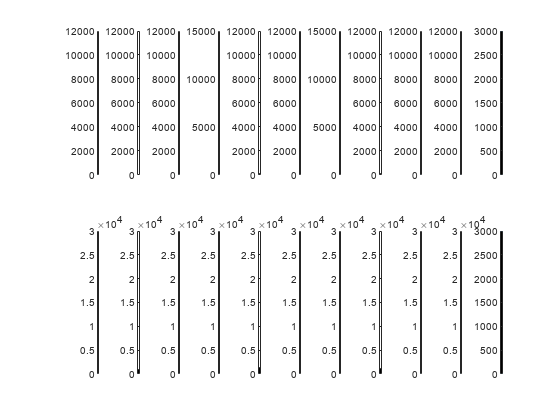

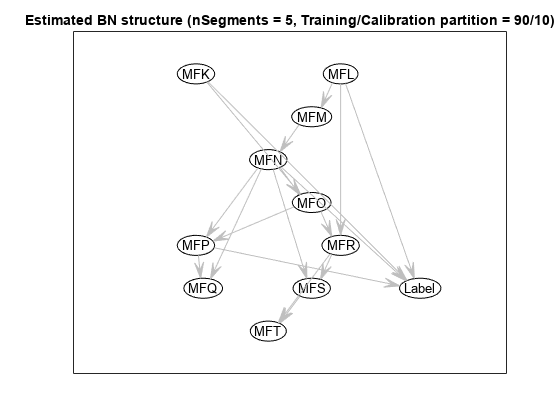

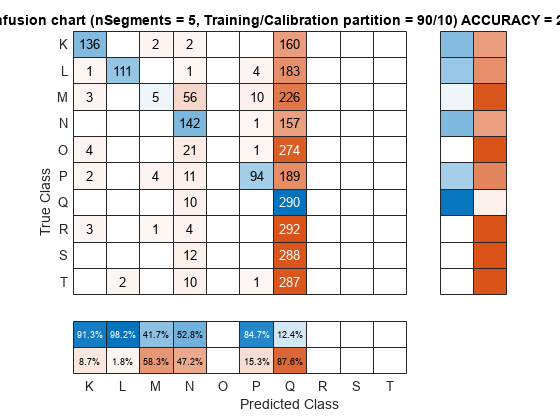

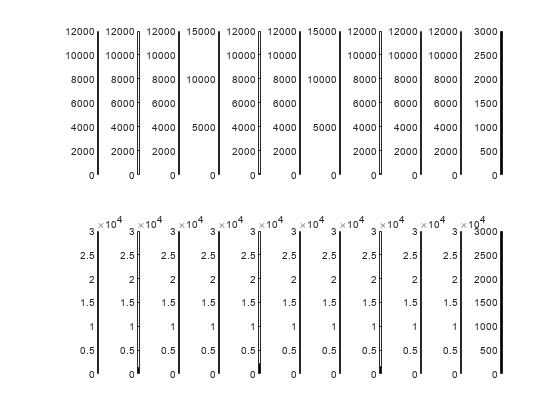

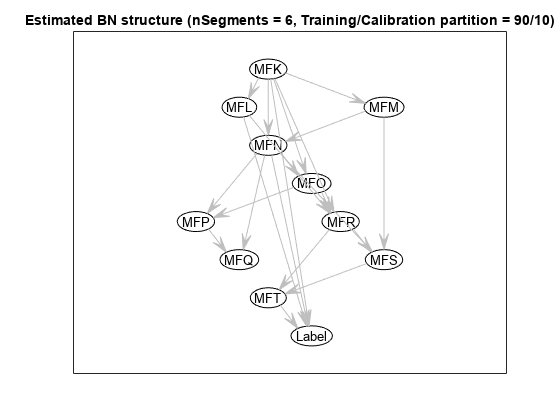

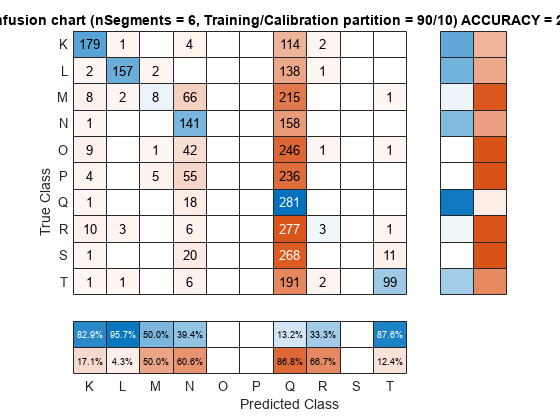

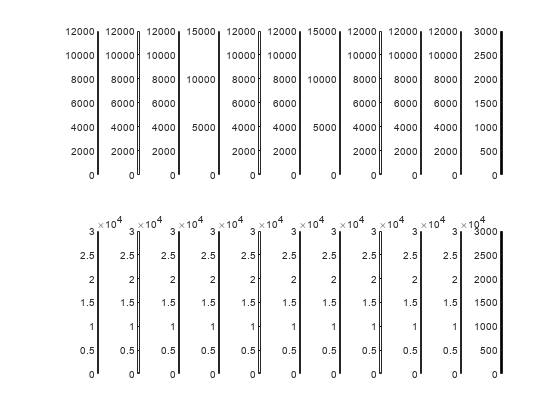

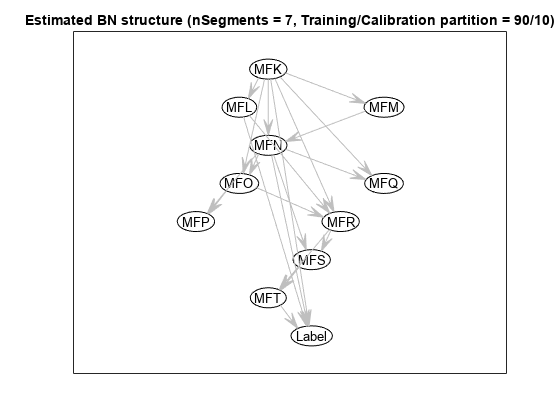

if Bayesian_training

BNtemp = mk_bnet(DAGhat, node_sizes);

for i = 1:col
    BNtemp.CPD{variable(i).node} = tabular_CPD(BNtemp, variable(i).node);
end

BNhat = learn_params(BNtemp, cases);

CPThat = cell(1, col);
for i = 1:col
    s = struct(BNhat.CPD{i});
    CPThat{i} = s.CPT;
end


figure;
draw_graph(BNhat.dag, varLabels);
title(sprintf("Estimated BN structure (nSegments = %d, Training/Calibration partition = %d/%d)", nseg, 100-partition_rate*100, partition_rate*100));

%Classification
engine       = global_joint_inf_engine(BNhat);

if (nseg == nSeg_chosen) && (partition_rate == partition_rate_chosen)
    save services\engine1.mat engine variable nseg seg_mat
end
[rowT, colT] = size(dataCal);

try
    for j = 1:rowT
        evidence     = [];
        evidence     = cell(1,colT);
        
        for i = 1:colT-1
           evidence{variable(i).node} = dataCal(j,i);
        end
        [engine, logLikelihood] = enter_evidence(engine, evidence);
        marginal       = marginal_nodes(engine, variable(end).node);
        totProb        = sum(marginal.T(:));
        dataPoint(j).M = marginal.T ./ totProb;
        [~, dataPoint(j).yhat] = max(dataPoint(j).M);
    end
    
    Ypred = categorical([dataPoint.yhat]');
    Ytrue = categorical(dataCal(:,end));
    
    accuracy = sum(Ypred==Ytrue)/length(Ytrue);
    ACCURACY_CAL(nseg_i,partition_rate_i) = accuracy;
    figure;
    cm = confusionmat(Ytrue, Ypred);
    results = confusionchart(cm, class_list, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
    results.title(sprintf("Confusion chart (nSegments = %d, Training/Calibration partition = %d/%d) ACCURACY = %0.2f%%", nseg, 100-partition_rate*100, partition_rate*100, accuracy*100));
catch
    warning('Problems occurred.');
end
    end
end
end

## NAIVE BAYESIAN CLASSIFICATION STRUCTURE

if NaiveBayesian_training

% load extracted_features\Xtrain_extracted.mat Xtrain_extracted
load extracted_features\Xtrain_nMatchedFeatures_table.mat Xtrain_nMatchedFeatures_table
Xtrain_extracted = Xtrain_nMatchedFeatures_table;
load extracted_features\Ytrain.mat Ytrain

% Examine correlation of variables
Xtrain_extracted_mat = table2array(Xtrain_extracted);
NB_corr = corrcoef(Xtrain_extracted_mat);
figure;
imagesc(NB_corr)
colormap(gca,'parula');
colorbar();
clim([0 1]);
axis equal
axis tight
title('Variable correlation in the extracted training data for Naive Bayesian training');
drawnow;

% varLabels = ["SP1x", "SP1y", "SP2x", "SP2y", "SP3x", "SP3y", "SP4x", "SP4y", "SP5x", "SP5y","MFK","MFL","MFM","MFN","MFO","MFP","MFQ","MFR","MFS","MFT", "Label"];
varLabels = ["MFK","MFL","MFM","MFN","MFO","MFP","MFQ","MFR","MFS","MFT", "Label"];
class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"];                                    % All classes included in this project
class_list = sort(class_list);

% Ytrain = grp2idx(categorical(Ytrain));
[nXtrain, nCol] = size(Xtrain_extracted);

Xtrain_extracted.Label = Ytrain;

cv = cvpartition(nXtrain, "HoldOut", 0.8);
Xtrain_nb_i = training(cv);
Xval_nb_i = test(cv);

Xtrain_nb = Xtrain_extracted(Xtrain_nb_i,:);
Ytrain_nb = Ytrain(Xtrain_nb_i,:);

Xval_nb = Xtrain_extracted(Xval_nb_i,:);
Yval_nb = Ytrain(Xval_nb_i,:);


NBmdl = fitcnb(Xtrain_nb, "Label");
LabelPred = predict(NBmdl, Xval_nb);
LabelPred = convertCharsToStrings(LabelPred);
figure;
ConfusionMat1 = confusionchart(Yval_nb,LabelPred);
accuracy_nb = sum(Yval_nb==LabelPred)/length(Yval_nb)
% save services\naiveBayesMdl.mat NBmdl
end

## TESTING BAYESIAN NETWORK MODEL AND NAIVE BAYESIAN MODEL

Function "sign_language_detect.m" can be used to make prediction either from loaded grayscale image data matrix or from a path-to-image. "Visual" flags can be used to allow visualization and plotting.

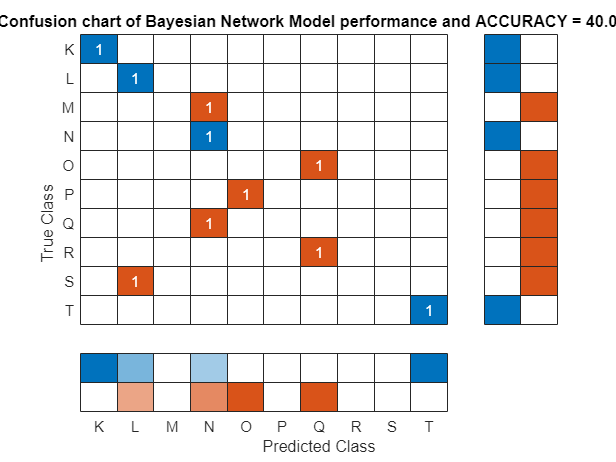

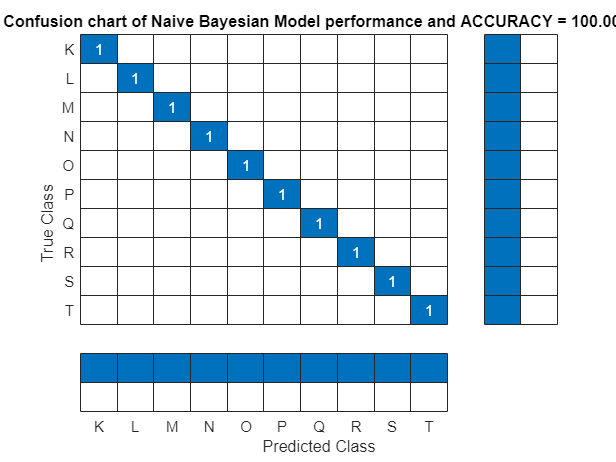

if Bayesian_testing

class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"];                                    % All classes included in this project
class_list = sort(class_list);
nClass = length(class_list);
test_data_path = "./data/asl_alphabet_test/asl_alphabet_test";                                     % File path to the directory of test data
nTestSamplePerClass = zeros(nClass, 1);

file_list = dir(test_data_path);
file_list = file_list(3:end);
regex_class = sprintf('%s-%s', class_list(1), class_list(end));
regex_file_name = sprintf('^(?<file_name>[%s]_test.jpg)', regex_class);
test_files_cell = regexpi({file_list.name}, regex_file_name, 'names','lineanchors');
test_files = vertcat(test_files_cell{:});
nXtest = length(test_files);

YtestPredBN = [];
YtestPredNB = [];
YtestTrue = [];

for f = 1:nXtest
    file_name = test_files(f).file_name;
    path_to_image = sprintf(test_data_path + "/" + file_name);

    % Predict with model trained with Bayesian Network
    YtestPredBNf = sign_language_detect(path_to_image, false);
    YtestPredBN = [YtestPredBN; YtestPredBNf];
    
    % Predict with model trained with Naive Bayesian structure
    YtestPredNBf = sign_language_detect_naivebayes(path_to_image, false);
    YtestPredNB = [YtestPredNB; YtestPredNBf];
    
    % Get true class from file name
    YtestTruef = string(file_name(1));
    YtestTrue = [YtestTrue; YtestTruef];
end
% Confusion Chart and Accuracy of the trained Bayesian Network on the test
% data
TestAccuracyBN = sum(YtestPredBN==YtestTrue)/length(YtestTrue);
figure;
cmTestBN = confusionmat(YtestTrue, YtestPredBN);
TestresultsBN = confusionchart(cmTestBN, class_list, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
TestresultsBN.title(sprintf("Confusion chart of Bayesian Network Model performance and ACCURACY = %0.2f%%", TestAccuracyBN*100));


% Confusion Chart and Accuracy of the trained Naive Bayesian structure on the test
% data
TestAccuracyNB = sum(YtestPredNB==YtestTrue)/length(YtestTrue);
figure;
cmTestNB = confusionmat(YtestTrue, YtestPredNB);
TestresultsNB = confusionchart(cmTestNB, class_list, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
TestresultsNB.title(sprintf("Confusion chart of Naive Bayesian Model performance and ACCURACY = %0.2f%%", TestAccuracyNB*100));
end

## B CONVOLUTIONAL NEURAL NETWORK TRAINING

## 1 Loading images

### 1.1 Load training images into datastore

if CNN_transfer_learning_retraining_without_noise || CNN_transfer_learning_retraining_with_noise

% List of classes included into training
class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"]; 
class_list = sort(class_list);

% File path to the directory of training images
train_data_path = "./data/asl_alphabet_train/asl_alphabet_train"; 
class_dir = dir(train_data_path);

% Get fullpaths to subfolders of included classes
train_data_path_folders_classes = class_dir(ismember(string({class_dir.name}),class_list),:);

train_data_path_folders = num2cell(string({train_data_path_folders_classes.folder}))';
train_data_path_folders = [train_data_path_folders{:}]';
train_data_path_folders_name = num2cell(string({train_data_path_folders_classes.name}))';
train_data_path_folders_name = [train_data_path_folders_name{:}]';

train_data_path_folders_full = train_data_path_folders + "\" + train_data_path_folders_name;

% Read all training images into an image datastore
imds_train_all = imageDatastore(train_data_path_folders_full, "IncludeSubfolders", true, "LabelSource", "foldernames", "FileExtensions", ".jpg");
nTrainSamplePerClass = countEachLabel(imds_train_all);
Ytrain = imds_train_all.Labels;
nClass = numel(categories(Ytrain));
imds_train_all.ReadSize = 3000;

% Partition the training data set for training and validation
partition_rate_train = 0.7;
[imds_train, imds_val] = splitEachLabel(imds_train_all, partition_rate_train, 'randomized');

nTrainSamplePerClass_train = countEachLabel(imds_train);
nTrainSamplePerClass_val = countEachLabel(imds_val);
end

### 1.2 Load testing images into datastore

if CNN_transfer_learning_testing

class_list = ["K", "L", "M", "N", "O", "P", "Q", "R", "S", "T"];                                    % All classes included in this project
class_list = sort(class_list);
nClass = length(class_list);
test_data_path = "./data/asl_alphabet_test/asl_alphabet_test";                                     % File path to the directory of test data
nTestSamplePerClass = zeros(nClass, 1);

file_list = dir(test_data_path);
regex_class = sprintf('%s-%s', class_list(1), class_list(end));
regex_file_name = sprintf('^(?<file_name>[%s]_test.jpg)', regex_class);
test_files_cell = regexpi({file_list.name}, regex_file_name, 'names','lineanchors');
test_files = vertcat(test_files_cell{:});
nXtest = length(test_files);

test_file_names = num2cell(string({test_files.file_name}));
test_file_names = [test_file_names{:}]';

% Get true class from file name
YtestTrue = arrayfun(@(file_name) extract(file_name, 1), test_file_names);
YtestTrue = categorical(YtestTrue);

% Get file paths to all test image file
test_images_directory = "./data/asl_alphabet_test/asl_alphabet_test";
test_file_paths = repmat(test_images_directory, nXtest, 1) + "/" + test_file_names;

% Read test images into an image datastore
imds_test = imageDatastore(test_file_paths, "IncludeSubfolders", true, "FileExtensions", ".jpg");
imds_test.Labels = YtestTrue;
imds_test_files = imds_test.Files;
imds_test.ReadSize = 500;

end

## 2 Transfer learning with original training data augmented with random reflection and translation

### 2.1 Transfer learning

if CNN_transfer_learning_retraining_without_noise
    
% Get resnet18 pretrained DNN
pretrained_model_name = "resnet18";     % TO TRY OTHER PRETRAINED MODEL => CHANGE THIS
net = resnet18;                         % TO TRY OTHER PRETRAINED MODEL => CHANGE THIS
inputSize = net.Layers(1).InputSize;

% Define options for data augmentation (allowing resizing, randomized reflection and translation)
pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);

% Apply data augmentation onto train set and validation set
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imds_train, 'DataAugmentation',imageAugmenter);
augimdsVal = augmentedImageDatastore(inputSize(1:2),imds_val);

% Modify DNN structure
lgraph = layerGraph(net);
newLearnableLayer = fullyConnectedLayer(nClass, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassLayer);

% Define training options
options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',4, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsVal, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress', ExecutionEnvironment="auto");

% Start transfer learning from the pretrained DNN
fprintf("Learning transfering from the pretrained DNN model %s ... \n", pretrained_model_name);
netTransfer = trainNetwork(augimdsTrain,lgraph,options);

% Save the retrained model of folder "services"
if SAVE_NEWLY_TRAINED_CNN_MODEL
save_model_to_path = sprintf("services\\%s_transferednet.mat", pretrained_model_name);
save(save_model_to_path, 'netTransfer', 'inputSize');
end

end

### 2.2 Testing the model trained in 2.1 with unchanged test images

model_name = "resnet18_transferednet"

path_to_trained_model = "services\resnet18_transferednet.mat"

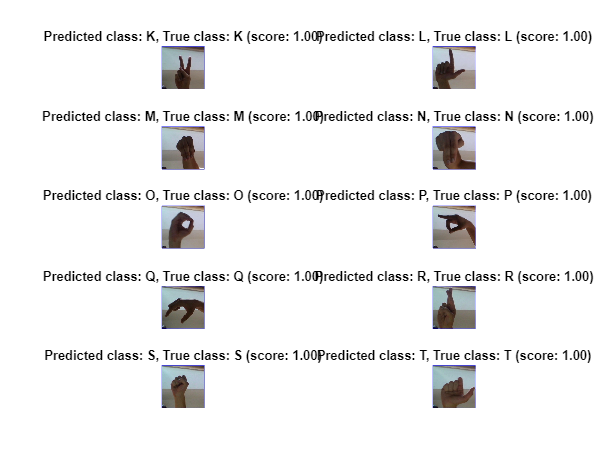

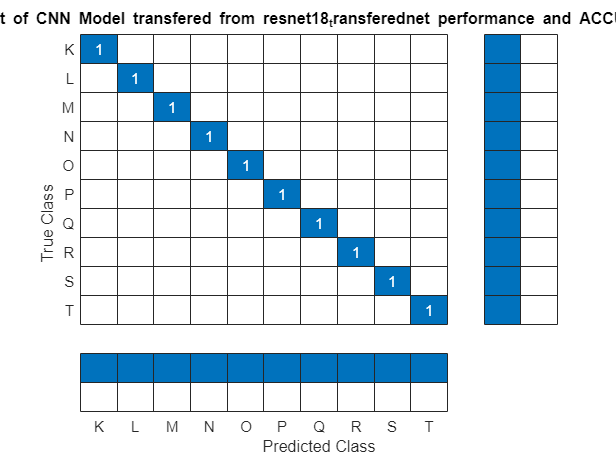

if CNN_transfer_learning_testing

% Load trained model
model_name = "resnet18_transferednet"
path_to_trained_model = sprintf("services\\%s.mat", model_name)
load(path_to_trained_model, 'netTransfer', 'inputSize');
augimdsTest = augmentedImageDatastore(inputSize(1:2), imds_test);

% Perform classification
YtestTrue = imds_test.Labels;
[YtestPred, scorestest] = classify(netTransfer,augimdsTest);
idx = randperm(numel(imds_test.Files),4);

figure;
for i = 1:size(YtestTrue,1)
    subplot(5,2,i)
    I = readimage(imds_test, i);
    imshow(I);
    Predlabel = YtestPred(i);
    Truelabel = YtestTrue(i);
    title(sprintf("Predicted class: %s, True class: %s (score: %0.2f)", string(Predlabel), string(Truelabel), max(scorestest(i,:))));
end

TestAccuracyCNN = mean(YtestPred == YtestTrue);
figure;
cmTestCNN = confusionmat(YtestTrue, YtestPred);
TestresultsCNN = confusionchart(cmTestCNN, class_list, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
TestresultsCNN.title(sprintf("Confusion chart of CNN Model transfered from %s performance and ACCURACY = %0.2f%%", model_name, TestAccuracyCNN*100));

end

## 3 Transfer learning with training images having Gaussian noise, motion blur effect and x-, y- translation randomly added

### 3.1 Transfer learning

if CNN_transfer_learning_retraining_with_noise
    
% Get resnet18 pretrained DNN
pretrained_model_name = "resnet18";     % TO TRY OTHER PRETRAINED MODEL => CHANGE THIS
net = resnet18;                         % TO TRY OTHER PRETRAINED MODEL => CHANGE THIS
inputSize = net.Layers(1).InputSize;

% Define options for data augmentation (allowing resizing, reflection and translation)
pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);

% Split data for with and without noise added
partition_rate_noise = 0.5;
[imds_train_with_before_noise, imds_train_without_noise] = splitEachLabel(imds_train, partition_rate_noise, 'randomized');
[imds_val_with_before_noise, imds_val_without_noise] = splitEachLabel(imds_val, partition_rate_noise, 'randomized');

nTrainSamplePerClass_train_with_noise = countEachLabel(imds_train_with_before_noise);
nTrainSamplePerClass_train_without_noise = countEachLabel(imds_train_without_noise);
nTrainSamplePerClass_val_with_noise = countEachLabel(imds_val_with_before_noise);
nTrainSamplePerClass_val_without_noise = countEachLabel(imds_val_without_noise);

% Resize only
imds_train_without_noise = transform(imds_train_without_noise,@image_resize_pipeline, 'IncludeInfo',true);
imds_val_without_noise = transform(imds_val_without_noise,@image_resize_pipeline, 'IncludeInfo',true);

figure;
dataPreview_imds_train_without_noise = preview(imds_train_without_noise);
montage(dataPreview_imds_train_without_noise(:,1))
title("Resized Images for Image Classification Training")
drawnow;

% Add noise
imds_train_with_noise_after_transformed = transform(imds_train_with_before_noise,@image_add_noise_pipeline, 'IncludeInfo',true);
imds_val_with_noise_after_transformed = transform(imds_val_with_before_noise,@image_add_noise_pipeline, 'IncludeInfo',true);

figure;
dataPreview_imds_train_with_noise_after_transformed = preview(imds_train_with_noise_after_transformed);
montage(dataPreview_imds_train_with_noise_after_transformed(:,1))
title("Augmented Images for Image Classification Training")
drawnow;

imds_train_combined = combine(imds_train_without_noise, imds_train_with_noise_after_transformed);
imds_val_combined = combine(imds_val_without_noise, imds_val_with_noise_after_transformed);

% Modify DNN structure
lgraph = layerGraph(net);
newLearnableLayer = fullyConnectedLayer(nClass, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassLayer);

% Define training options
options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',4, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imds_val_combined, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress', ExecutionEnvironment = "auto");

% Start transfer learning from the pretrained DNN
fprintf("Learning transfering from the pretrained DNN model %s ... \n", pretrained_model_name);
netTransfer = trainNetwork(imds_train_combined,lgraph,options);

% Save the retrained model of folder "services"
if SAVE_NEWLY_TRAINED_CNN_MODEL
save_model_to_path = sprintf("services\\%s_transferednet_with_noise.mat", pretrained_model_name);
save(save_model_to_path, 'netTransfer', 'inputSize');
end

end

## 3.2 Testing the model trained in 3.1 with test images having noise, blur and translation added

model_name = "resnet18_transferednet_with_noise"

path_to_trained_model = "services\resnet18_transferednet_with_noise.mat"

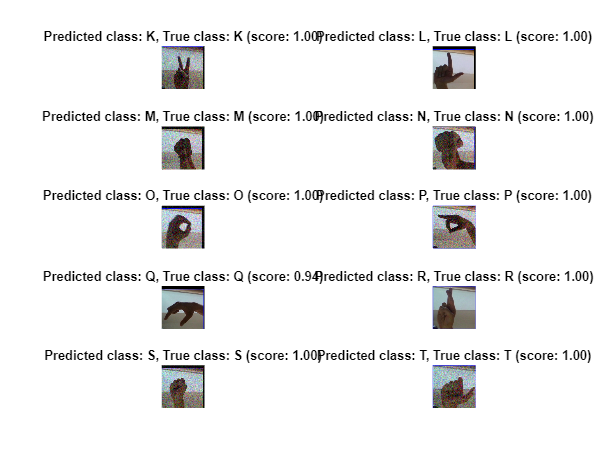

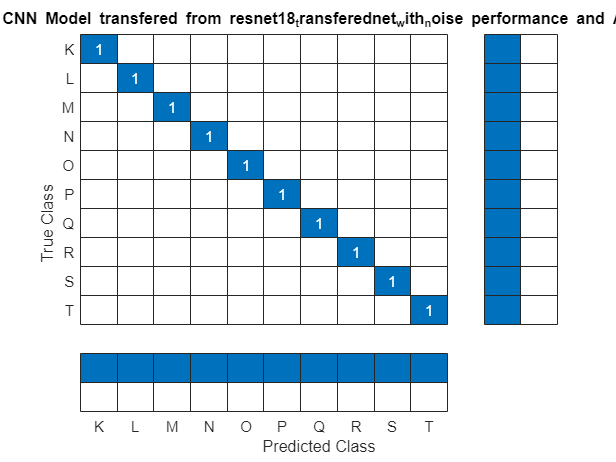

if CNN_transfer_learning_testing

% Add noise and blur motion to test data to trick the model
imds_test_with_noise = transform(imds_test,@image_add_noise_pipeline, 'IncludeInfo',true);

% Load trained model
model_name = "resnet18_transferednet_with_noise"
path_to_trained_model = sprintf("services\\%s.mat", model_name)
load(path_to_trained_model, 'netTransfer', 'inputSize');

% Perform classification
YtestTrue = imds_test.Labels;
[YtestPred, scorestest] = classify(netTransfer,imds_test_with_noise);

imgs_test_with_noise = read(imds_test_with_noise);
figure;
for i = 1:size(imgs_test_with_noise,1)
    subplot(5,2,i)
    I = imgs_test_with_noise{i,1};
    imshow(I);
    Predlabel = YtestPred(i);
    Truelabel = YtestTrue(i);
    title(sprintf("Predicted class: %s, True class: %s (score: %0.2f)", string(Predlabel), string(Truelabel), max(scorestest(i,:))));
end

TestAccuracyCNN = mean(YtestPred == YtestTrue);
figure;
cmTestCNN = confusionmat(YtestTrue, YtestPred);
TestresultsCNN = confusionchart(cmTestCNN, class_list, 'ColumnSummary','column-normalized', 'RowSummary', 'row-normalized');
TestresultsCNN.title(sprintf("Confusion chart of CNN Model transfered from %s performance and ACCURACY = %0.2f%%", model_name, TestAccuracyCNN*100));

end